%% init
clear all; clc;close all;
addpath( "Functions","Nasa");

global Runiv
Runiv = 8.314;
[SpS,El]        = myload('Nasa\NasaThermalDatabase.mat',{'Diesel','O2','N2','CO2','H2O'});
MO2 = 0;
MN2 = 0.7173;
MCO2 = 0.2031;
MH2O = 0.0796;
Yout = [0, MO2, MN2, MCO2, MH2O];
M = [0.167, 0.032 0.0280134 0.04401 0.018015];



T = [0: 1: 2500]

T =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


Ntemp = length(T);
Nspecies = length(SpS);

for iT = 1:Ntemp
    for iS = 1:Nspecies
        Cp(iT, iS) = CpNasa(T(iT), SpS(iS));
    end
end

Cp_mix = Cp * Yout';


for iT = 1:Ntemp
    for iS = 1:Nspecies
        Cv(iT, iS) = CvNasa(T(iT), SpS(iS));
    end
end

Cv_mix = Cv * Yout';


%Get gamma with thisThe  cp and cv
gamma = Cp_mix./Cv_mix

gamma =     1.4371
    1.4367
    1.4363
    1.4359
    1.4356
    1.4352
    1.4348
    1.4345
    1.4341
    1.4337


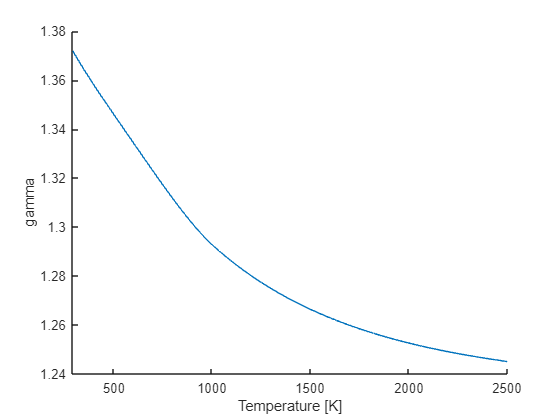


figure;
hold on;
plot(gamma)
xlim([293 2500]);
xlabel('Temperature [K]')
ylabel('gamma')
hold off;